# **TU: Time-Domain Statistical Features**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Extract Time-Domain Features of a Simple Sinewave

## Include path

addpath('../../Library')  

## Dataset

### Generate Signals

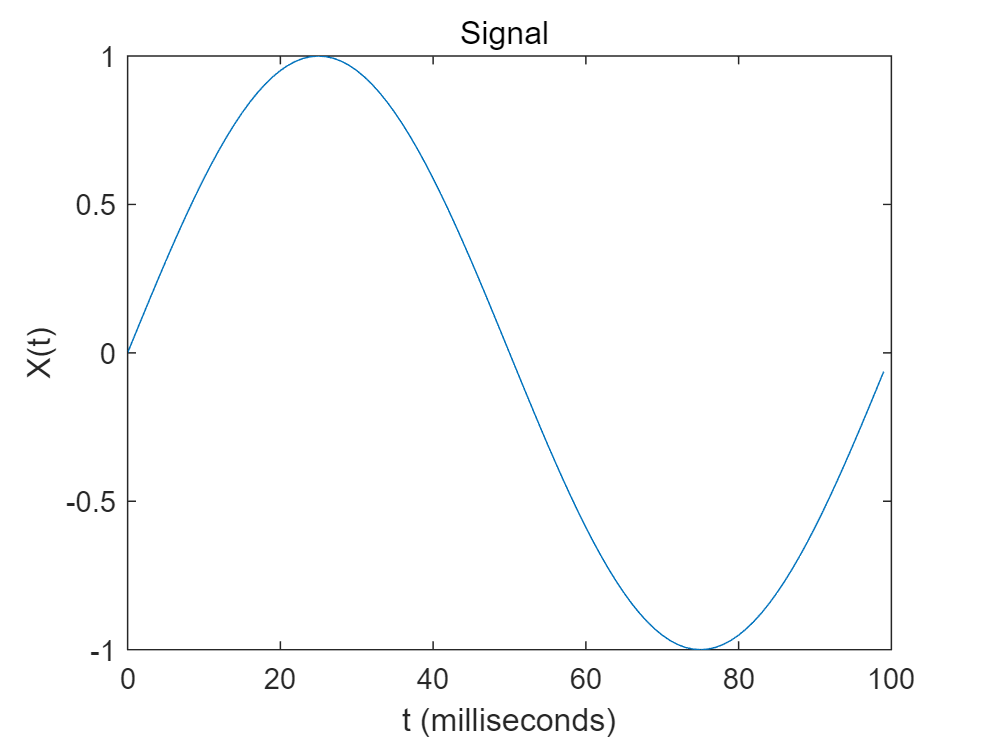

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 100;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
fa=10;      % 10Hz signal
fa2=55;    % 55Hz signal
X = 0.0 + 1 * sin(2.0*pi*fa*t)+0*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

### Mix Signal with Noise

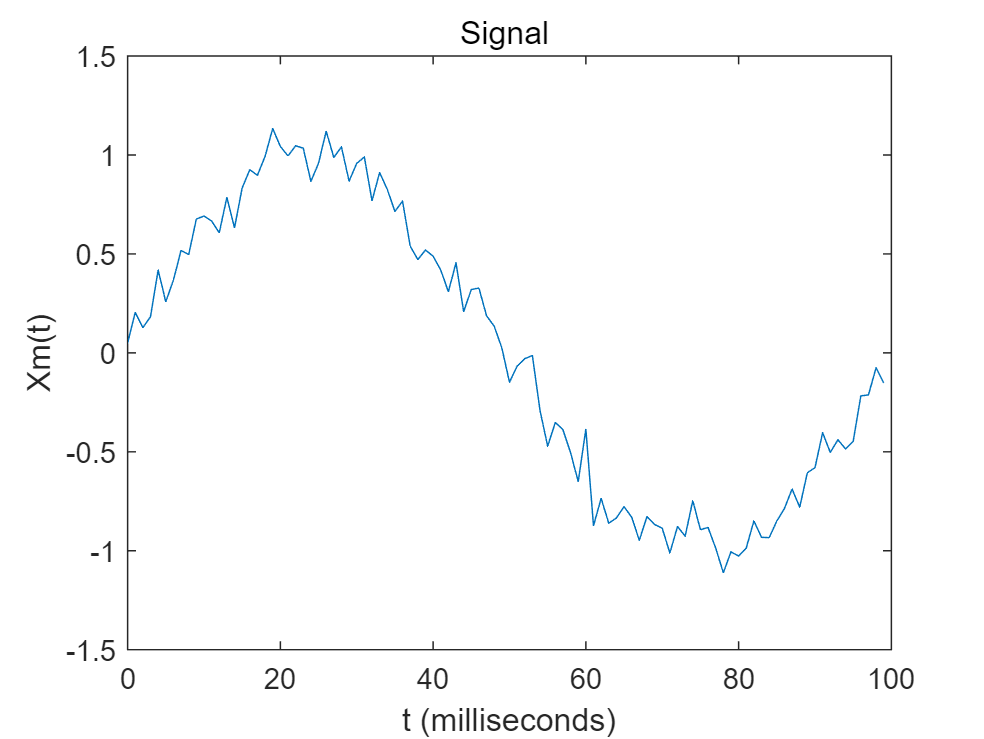


% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xn = 1 * sin(2.0*pi*fa*t)+noise; 


% Plot signals
figure()
plot(1000*t,Xn)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('Xm(t)')

## Exercise:  Time-Domain Features  

Obtain the following features in time domain. Compare your code with MATLAB functions

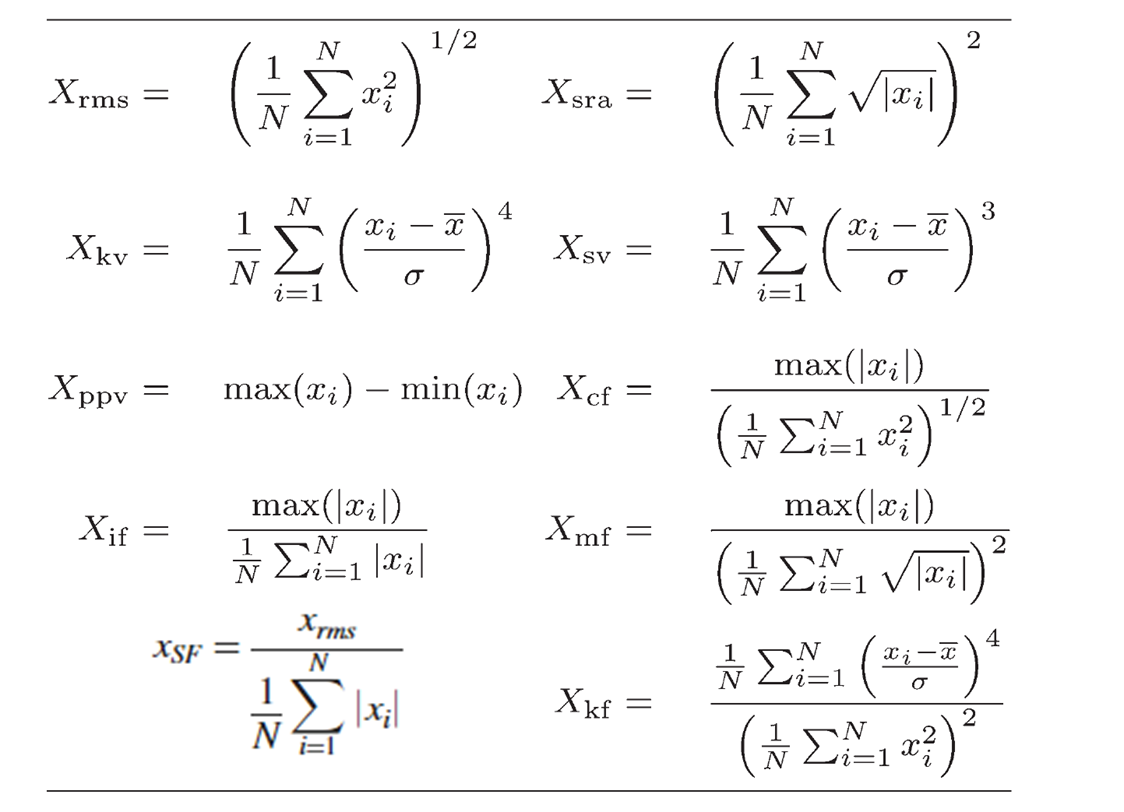

% x:        Input data
% xfeature: Table for feature of x

x=Xn;        % x=X % without noise
xfeature = table;
N=length(x);


%% mean and STD
xfeature.mean=mean(x);
xfeature.std=std(x);

%% RMS
%**** Your code goes here ****
xfeature.rms=0;

xrms = 0.7116

%% Square Root Average
%**** Your code goes here ****
xfeature.sra=0;

%% Average of Absolute Value
xfeature.aav=sum(abs(x))/N;



%% Energy (sum of power_2)
xfeature.energy=sum(x.^2);


%% Peak
%**** Your code goes here ****
xfeature.peak=0

%% Peak2Peak
xfeature.ppv=peak2peak(x);


%% Impulse Factor
xfeature.if=xfeature.peak/xfeature.aav;

%% Shape Factor
xfeature.sf=xfeature.rms/xfeature.aav;

%% Crest Factor
%**** Your code goes here ****
xfeature.cf=0


% Marginal(Clearance) Factor
xfeature.mf=xfeature.peak/xfeature.sra;

%% Skewness
xfeature.sk=skewness(x);


%% Kurtosis
xfeature.kt=kurtosis(x);


% Print all features
xfeature

xfeature = 1×14 table
      mean        std        rms        sra        aav      energy     peak      ppv        if        sf        cf        mf         sk         kt  
    _________    ______    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    ________    ______

    -0.003735    0.7152    0.71163    0.58394    0.63901    50.641    1.1337    2.2448    1.7741    1.1136    1.5931    1.9414    0.031908    1.5416


## Exercise 2

Compare the time-domain features of signals with and without noise added.

## Exercise 3

Create a module, named as  `timeFeatures.m`  that returns time-domain features in table form.

Save it in `\IAIA\Library\` folder

See [**timeFeatures_student.m**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Library) as an example.

Example: 

xfeature=timeFeatures(x)

xfeature = 1×14 table
      mean        std        rms        sra        aav      energy     peak      ppv        if        sf        cf        mf         sk         kt  
    _________    ______    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    ________    ______

    -0.003735    0.7152    0.71163    0.58394    0.63901    50.641    1.1337    2.2448    1.7741    1.1136    1.5931    1.9414    0.031908    1.5416
